# Lecture 2: Lagrange equations of motion

## Introduction

- Find the kinetic energy of the system $T$. 

- Find the potential energy of the system $V$.  

- Find the generalized non conservative force vector $\underline{Q^{\textrm{nc}} }$. 

- Find the Equations of Motion

Choose the generalized coordinates $q=\left\lbrack \begin{array}{c}
\phi_1 \\
\phi_2 
\end{array}\right\rbrack$.

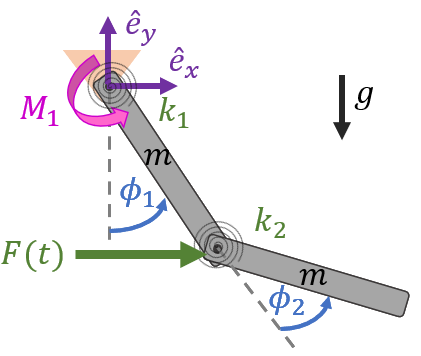

The length of each bar is L. Assume the following properties:

- L = 1                [m]

- m = 3               [kg]

- $M_1 \left(t\right)=2$        [Nm]

- $F\left(t\right)=\sin \left(t\right)$    [N]

- g = 9.81           [m/$s^{2\;}$]

- $k_1 =4$             [Nm/rad]

- $k_2 =2$             [Nm/rad]

## Kinetic Energy

The kinetic energy of each beam is


$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G } +\frac{1}{2}J_G \omega {\;}^2$$


where the mass moment of inertia for a thin homogenious beam about its center is $J_G =\frac{1}{12}{\textrm{mL}}^{2\;}$.

clc; clear all; close all;

syms phi_1 phi_2 phi_dot_1 phi_dot_2 phi_ddot_1 phi_ddot_2
syms t F(t) M_1(t)
syms L m g k_1 k_2
L = 1;
m = 3;
g = 9.81;
k_1 = 4;
k_2 = 2;

% Generalized Coordinates
q = [phi_1;
    phi_2];
q_dot = [phi_dot_1;
    phi_dot_2];
q_ddot = [phi_ddot_1;
    phi_ddot_2];

% Position vectors
r_1 = [L/2*sin(phi_1);
    -L/2*cos(phi_1)];
r_2 = [L*sin(phi_1)+L/2*sin(phi_1+phi_2);
    -L*cos(phi_1)-L/2*cos(phi_1+phi_2)];

% Velocity vectors
r_dot_1 = jacobian(r_1,q)*q_dot;
r_dot_2 = jacobian(r_2,q)*q_dot;

% Kinetic Energy
J = 1/12*m*L^2;
T_1 = 1/2*m*transpose(r_dot_1)*r_dot_1 + 1/2*J*phi_dot_1^2;
T_2 = 1/2*m*transpose(r_dot_2)*r_dot_2 + 1/2*J*(phi_dot_1+phi_dot_2)^2;
T = T_1 + T_2;
T = simplify(T)

$$T = \frac{3\,{{\dot{\varphi }}_{1}}^{2}\,\cos\left(\varphi_{2}\right)}{2}+{\dot{\varphi }}_{1}\,{\dot{\varphi }}_{2}+\frac{5\,{{\dot{\varphi }}_{1}}^{2}}{2}+\frac{{{\dot{\varphi }}_{2}}^{2}}{2}+\frac{3\,{\dot{\varphi }}_{1}\,{\dot{\varphi }}_{2}\,\cos\left(\varphi_{2}\right)}{2}$$

## Potential Energy

The elastic potential energy due to each torsional spring is shown. $\theta \;$is the rotation the bars have relative to each other. Neglect unstretched rotation ($\theta_0 =0$)


$$V_k =\frac{1}{2}{k\left(\theta -\theta_0 \right)}^{2\;}$$


The gravitational potential energy of each bar is shown. $y$ is the vertical height from the reference frame.


$$V_g =\textrm{mgy}$$


% Elastic Potential Energy
V_k_1 = 1/2*k_1*(phi_1)^2;
V_k_2 = 1/2*k_2*(phi_2)^2;

% Gravitational Potential Energy
V_g_1 = m*g*(-L/2*cos(phi_1));
V_g_2 = m*g*(-L*cos(phi_1)-L/2*cos(phi_1+phi_2));

% Combined
V = (V_k_1 + V_g_1) + (V_k_2 + V_g_2)

$$V = 2\,{\varphi_{1}}^{2}-\frac{8829\,\cos\left(\varphi_{1}\right)}{200}-\frac{2943\,\cos\left(\varphi_{1}+\varphi_{2}\right)}{200}+{\varphi_{2}}^{2}$$

## Generalized non-conservative force vector

First identify the non conservative forces $F_i$, and moments $M_j$. Then find the absolute position vectors $r_{i\;}$to the forces and absolute rotation vectors $\theta_j$ to the moments. 


$$Q^{\textrm{nc}} =\sum_{i=1}^{n_F } {\left(r_{i,q} \right)}^T F_i +\sum_{j=1}^{n_M } {\left(\theta {\;}_{j,q} \right)}^T M_j$$


% Force
r = [L*sin(phi_1);
    -L*cos(phi_1);
    0];
F_vec = [F(t);
    0;
    0];

% Moment
theta = [0;
    0;
    phi_1];
M_vec = [0;
    0;
    M_1(t)];

Q_nc = transpose(jacobian(r,q))*F_vec + transpose(jacobian(theta,q))*M_vec

$$Q\_nc = \left(\begin{array}{c} M_{1}\left(t\right)+F\left(t\right)\,\cos\left(\varphi_{1}\right)\\ 0 \end{array}\right)$$

## Lagrange Equations of Motion

The equations of motion for each of the generalized coordinates can be found from


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)-T,_q +V,_q ={\left(Q^{\textrm{nc}} \right)}^T$$


Note that the first term can be found from the chain rule. 


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;s}\dot{s} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{s} }\ddot{s} \right)}^T$$


But since there are no prescribed displacements ($s=0$) then


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} \right)}^T$$


% First term
dTdq_dot = jacobian(T,q_dot);
First_Term = jacobian(transpose(dTdq_dot),q)*q_dot + jacobian(transpose(dTdq_dot),q_dot)*q_ddot;
First_Term = transpose(First_Term); 

% Second term
Second_Term = jacobian(T,q);
Second_Term = simplify(Second_Term);

% Third term
Third_Term = jacobian(V,q);
Third_Term = simplify(Third_Term);

% Equation of Motion
EoM = First_Term - Second_Term + Third_Term == transpose(Q_nc);
EoM = simplify(EoM);
EoM = transpose(EoM)

$$EoM = \begin{array}{l} \left(\begin{array}{c} 4\,\varphi_{1}+\frac{\sigma_{1}}{200}+\frac{8829\,\sin\left(\varphi_{1}\right)}{200}+{\ddot{\varphi }}_{2}\,\left(\frac{3\,\cos\left(\varphi_{2}\right)}{2}+1\right)+{\ddot{\varphi }}_{1}\,\left(3\,\cos\left(\varphi_{2}\right)+5\right)-{\dot{\varphi }}_{2}\,\left(3\,{\dot{\varphi }}_{1}\,\sin\left(\varphi_{2}\right)+\frac{3\,{\dot{\varphi }}_{2}\,\sin\left(\varphi_{2}\right)}{2}\right)=M_{1}\left(t\right)+F\left(t\right)\,\cos\left(\varphi_{1}\right)\\ 300\,\sin\left(\varphi_{2}\right)\,{{\dot{\varphi }}_{1}}^{2}+400\,\varphi_{2}+200\,{\ddot{\varphi }}_{1}+200\,{\ddot{\varphi }}_{2}+\sigma_{1}+300\,{\ddot{\varphi }}_{1}\,\cos\left(\varphi_{2}\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2943\,\sin\left(\varphi_{1}+\varphi_{2}\right) \end{array}$$

## Simulation

*(don't worry if you don't understand the code below. A separate video & example will be provided showing you how to implement this easily in Simulink)*

One way to solve this is to put the equation of motion in state space form (beyond scope of this course) & to simulate it using ODE45.

EoM = subs(EoM,F(t),sin(t));    % F(t) = sin(t)
EoM = subs(EoM,M_1(t),2);       % M_1(t) = 2

syms phi_1(t) phi_2(t)
EoM = subs(EoM, {'phi_1', 'phi_2', 'phi_dot_1', 'phi_dot_2', 'phi_ddot_1', 'phi_ddot_2'}, [phi_1(t) phi_2(t), diff(phi_1,t), diff(phi_2,t), diff(phi_1,t,2), diff(phi_2,t,2)]);
EoM = formula(EoM);
[V, S] = odeToVectorField(EoM(1),EoM(2));
% y1 = phi_1
% y2 = d/dt phi_1
% y3 = phi_2
% y4 = d/dt phi_2
V_fun = matlabFunction(V,'vars',{'t','Y'});
t_interval = linspace(0,10,300);
y_IC = [0.2, 0, 0, 0];
[t_sol,y_sol] = ode45(V_fun,t_interval,y_IC);
phi_1_sol = y_sol(:,1);
phi_2_sol = y_sol(:,3);

% Plot
plot(t_sol,phi_1_sol)
hold on
plot(t_sol,phi_2_sol)
xlabel('t [seconds]')
title('F(t) = sin(t) & M_1(t) = 2')
legend('\phi_1 [rad]', '\phi_2 [rad]')

## Postprocessing - Animation

*(don't worry if you don't understand the code below. Knowing how to code this simulation is not part of the course)*

figure,
for ii=1:numel(phi_1_sol)
    plot_currentConfiguration(L, phi_1_sol(ii), phi_2_sol(ii))
    xlim([-1, 1])
    ylim([-2.2, 0])
    drawnow
end

## Auxiliary functions

function plot_currentConfiguration(L, phi1, phi2)
    X0 = 0;
    Y0 = 0;
    X1 = sin(phi1)*L;
    Y1 = -cos(phi1)*L;
    X2 = X1 + sin(phi1 + phi2)*L;
    Y2 = Y1 - cos(phi1 + phi2)*L;
    plot([X0 X1 X2], [Y0 Y1 Y2], 'k-', LineWidth=3, MarkerFaceColor='r')
    hold on;
    plot([X0 X1 X2], [Y0 Y1 Y2], 'ro', MarkerSize=10, MarkerFaceColor='r')
    hold off;
    axis equal
end